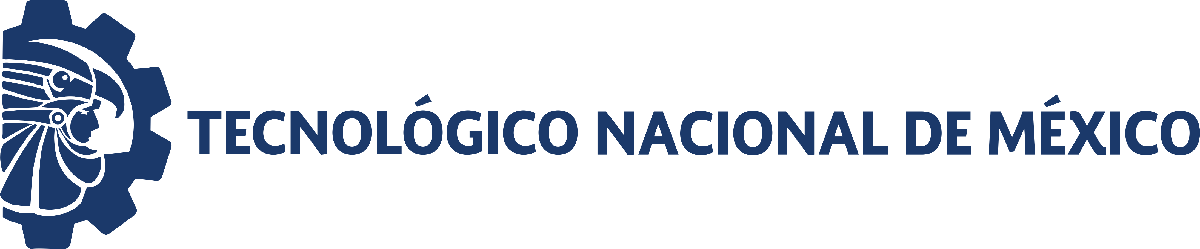                                 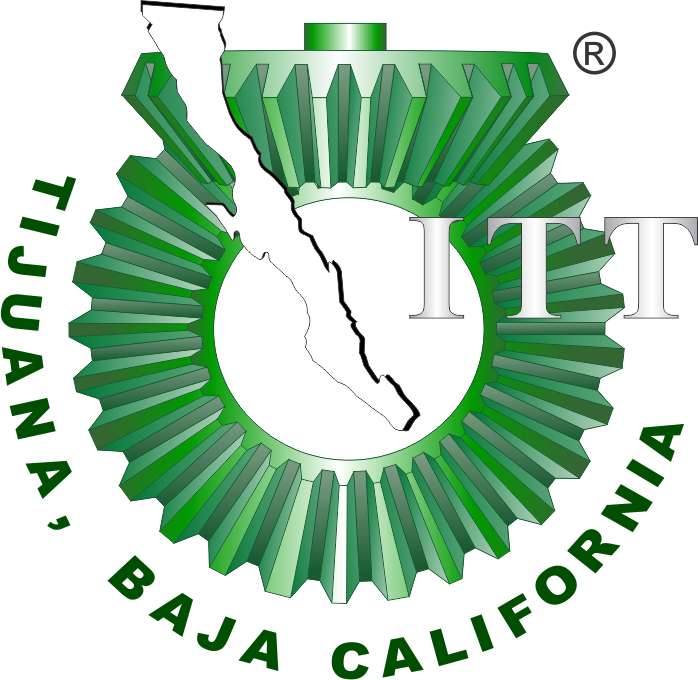

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

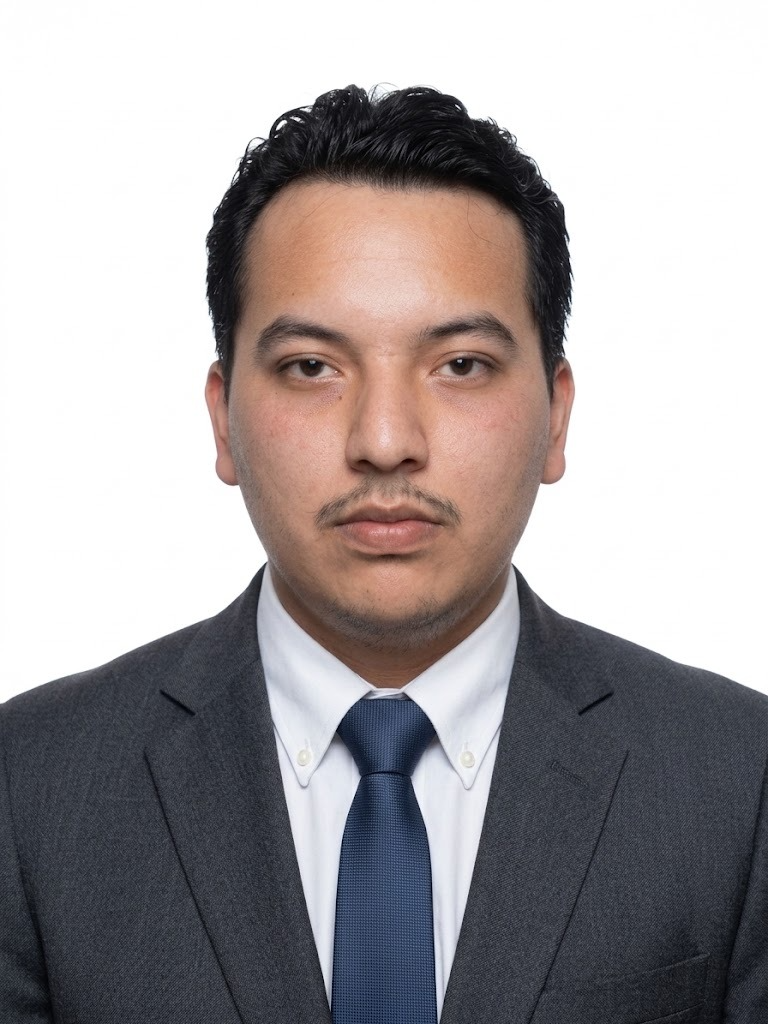

Nombre del alumno: **Garcia Grijalva Armando**

Número de control: **23212195**

Correo institucional: **L23212195@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema')
parameters.StopTime = '10'

parameters = struct with fields:
    StopTime: '10'


parameters.Solver = 'ode15s'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'


parameters.MaxStep = '1E-3'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'
     MaxStep: '1E-3'


% set_param('Sistema/PA(t): CE/PA','VectorFormat','1-D array');

## Respuesta al escalón

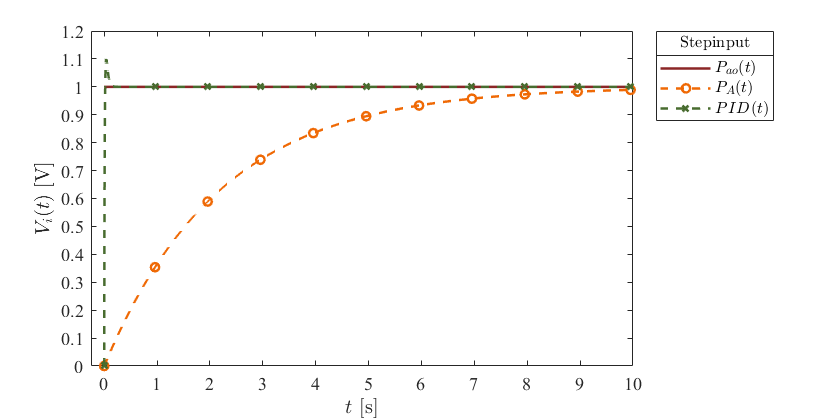

set_param('Sistema/S1','sw','1')
set_param('Sistema/Pao(t)','sw','1')
x1=sim('Sistema',parameters);
plotSignals(x1.t,x1.Pao,x1.PA,x1.PID,'Step')

## Respuesta al impulso

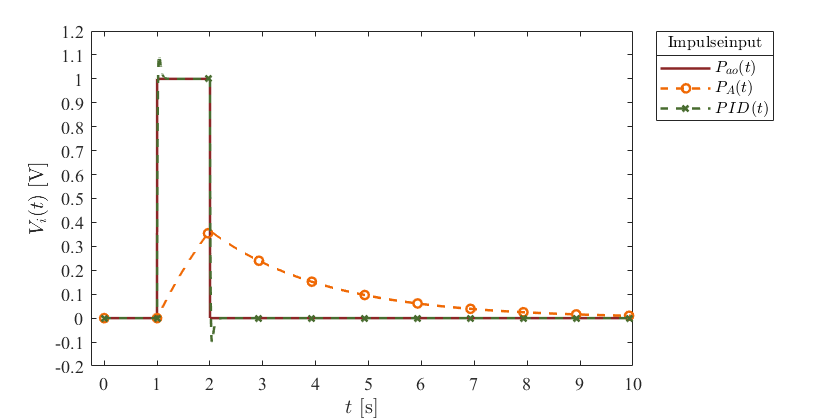

set_param('Sistema/S1','sw','0')
set_param('Sistema/Pao(t)','sw','1')
x2=sim('Sistema',parameters);
plotSignals(x2.t,x2.Pao,x2.PA,x2.PID,'Impulse')

## Respuesta a la rampa

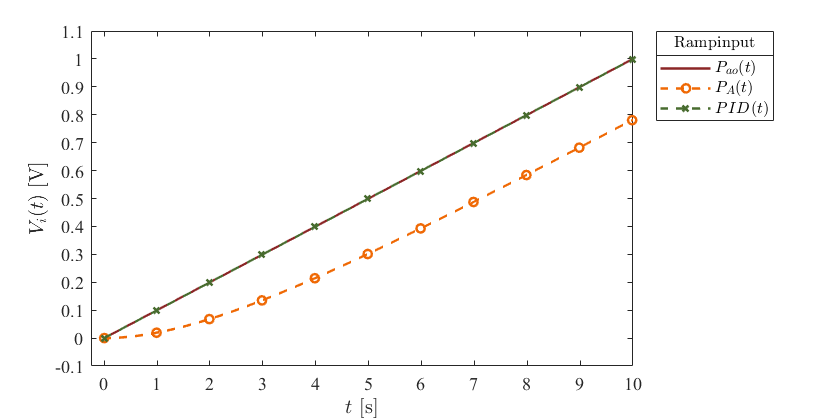

set_param('Sistema/S2','sw','1')
set_param('Sistema/Pao(t)','sw','0')
x3=sim('Sistema',parameters);
plotSignals(x3.t,x3.Pao,x3.PA,x3.PID,'Ramp')

## Respuesta a la función sinusoidal

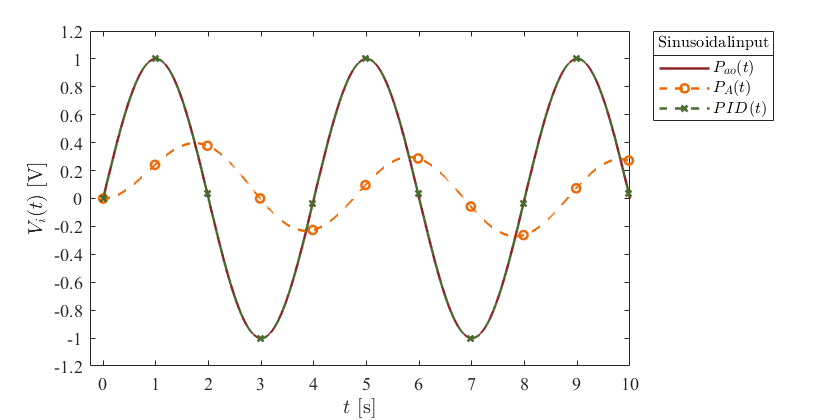

set_param('Sistema/S2','sw','0')
set_param('Sistema/Pao(t)','sw','0')
x4=sim('Sistema',parameters);
plotSignals(x4.t,x4.Pao,x4.PA,x4.PID,'Sinusoidal')

## Función: Respuestas de la simulación

function plotSignals(t,Pao,PA,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [139, 38, 38]/255;
    clr2 = [239, 105, 5]/255;
    clr3 = [72, 108, 47]/255;
    
    order = [clr1;clr2;clr3]; colororder(order)
    
    plot(t,Pao,'-',t,PA,'--o',t,PID,'--x','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    L = legend('$P_{ao}(t)$','$P_A(t)$','$PID(t)$');
    set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
    title(L,[signal,'input'])
    
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
    
    xlim([-0.25 10]); xticks(0:1:10)
    
    if signal == "Step"
        ylim([0 1.2]); yticks(0:0.1:1.2)
    elseif signal == "Impulse"
        ylim([-0.2 1.2]); yticks(-0.2:0.1:1.2)
    elseif signal == "Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    elseif signal == "Sinusoidal"
        ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)
    end
    
    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end